close all
clear


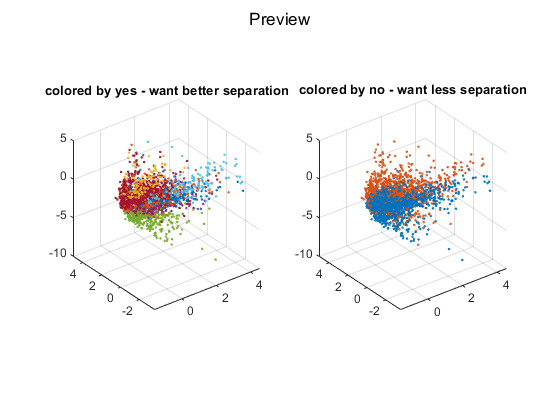

rng(2019)
dataset = load('retina.mat');
patient = dataset.patient;
type = dataset.type;
location = dataset.location;
dataset = dataset.expr;

c = 2;
n = size(dataset, 1);

no = patient;
yes = type;

figure
sgtitle('Preview')
subplot(1, 2, 1)
for t = unique(type)'
    scatter3(dataset(yes == t, 1), dataset(yes == t, 2), dataset(yes == t, 3), 2)
    hold on
end
pbaspect([1 1 1])
title('colored by yes - want better separation')

subplot(1, 2, 2)
scatter3(dataset(no == 1, 1), dataset(no == 1, 2), dataset(no == 1, 3), 2)
hold on
scatter3(dataset(no == 2, 1), dataset(no == 2, 2), dataset(no == 2, 3), 2)
pbaspect([1 1 1])
title('colored by no - want less separation')

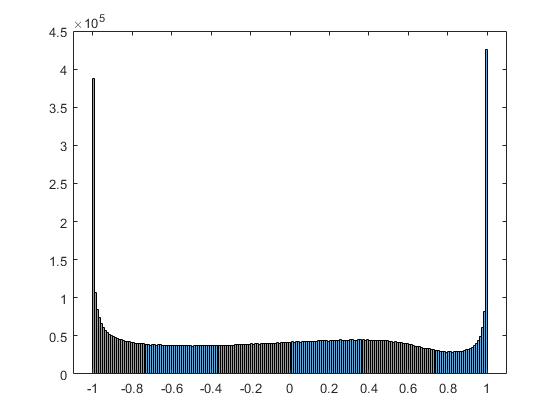

% symk = @(x) exp(-(mpdist(x) .^ 2) / (2 * 8 ^ 2)); % Gaussian RBF kernel
% symk = @(x) exp(mpdist(x) / 8); % Laplace RBF kernel
symk = @(x) tanh(0.4 * x * x' + 0); % sigmoid kernel
% symk = @(x) (x * x' + 2) .^ 2; % polynomial kernel
% symk = @(x) (x * x'); % linear kernel
% symk = @

K = symk(dataset);

figure
histogram(K(:))

## AAT

top = zeros(c, 1);
bot = zeros(c, 1);
num = zeros(c, 1);
for a = 1 : c
    num(a) = sum(no == a);
    if a == 1
        top(a) = 1;
    else
        top(a) = top(a - 1) + n - num(a - 1);
    end
    bot(a) = top(a) + n - num(a) - 1;
end

AAT = zeros((c - 1) * n);
for a = 1 : c
    for b = 1 : (a - 1)
        term2 = mean(mean(K(no == a, no == b)));
        term3 = mean(K(no == a, no ~= b), 1);
        term4 = mean(K(no ~= a, no == b), 2);
        
        AAT(top(a) : bot(a), top(b) : bot(b)) = K(no ~= a, no ~= b) + term2 - term3 - term4;
        AAT(top(b) : bot(b), top(a) : bot(a)) = AAT(top(a) : bot(a), top(b) : bot(b))';
    end
    
    b = a;
    term2 = mean(mean(K(no == a, no == b)));
    term3 = mean(K(no == a, no ~= b), 1);
    term4 = mean(K(no ~= a, no == b), 2);
    
    AAT(top(a) : bot(a), top(b) : bot(b)) = K(no ~= a, no ~= b) + term2 - term3 - term4;
end

% AAT = AAT / eigs(AAT, 1);

## distances

term11 = zeros(n, c);
for a = 1 : c
    term11(:, a) = mean(K(:, no == a), 2);
end

ind1 = [];
ind2 = [];
for a = 1 : c
    ind1 = [ind1 find(no ~= a)'];
    ind2 = [ind2 (zeros(1, n - num(a)) + a)];
end

% Note: these only apply to RBF kernel
DE = sqrt(diag(K) + diag(K)' - K - K');
DEAAT = sqrt(diag(AAT)); % column vector

O = zeros(n);

for jj = 1 : n
    vec = K(jj : n, ind1) - K(jj, ind1) + term11(jj, ind2) - term11(jj : n, ind2);
    %O(jj : n, jj) = (sum((vec ./ DE(jj : n, jj) ./ DEAAT') .^ 10, 2) / (c - 1) / n) .^ (1/10);
    O(jj : n, jj) = max(abs(vec ./ (DE(jj : n, jj) + 1e-9) ./ DEAAT'), [], 2);
end

O = O + (O' .* (1 - eye(n)));

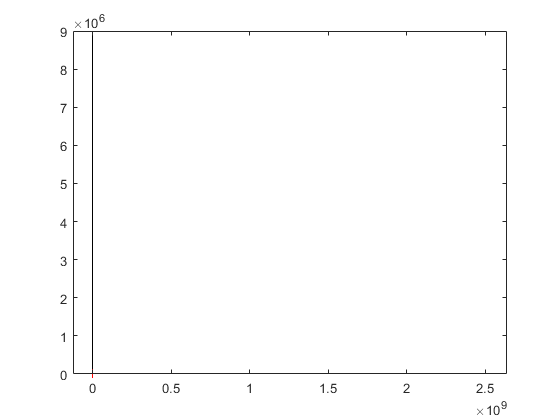

sorted = sort(O(:));
sorted = sorted(sorted > 0);
th2 = sorted(800);

figure
histogram(O(:));
hold on
plot(th2, 0, '+r')


orth_sub1 = [];
orth_sub2 = [];
for ii = 1 : n
    for jj = 1 : (ii - 1)
        if O(ii, jj) <= th2
            orth_sub1 = [orth_sub1 ii];
            orth_sub2 = [orth_sub2 jj];
        end
    end
end

BBT = K(orth_sub1, orth_sub1) + K(orth_sub2, orth_sub2) - K(orth_sub1, orth_sub2) - K(orth_sub2, orth_sub1);

th = 1e-12;
r = min(2000, size(BBT, 1));

[u, s] = eigs(BBT, r);
s = diag(s);
mask = s / max(s) > th;
s = s(mask);
u = u(:, mask);



D = zeros(n);
for jj = 1 : n
    vec = K(jj : n, orth_sub1) - K(jj, orth_sub1) + K(jj, orth_sub2) - K(jj : n, orth_sub2);
    D(jj : n, jj) = sqrt(sum((vec * u) .^ 2 ./ sqrt(s'), 2));
end

%   ./ s'

D = D + (D' .* (1 - eye(n)));

umap_obj = umap();
umap_obj.metric = 'precomputed';
R = umap_obj.fit(D);

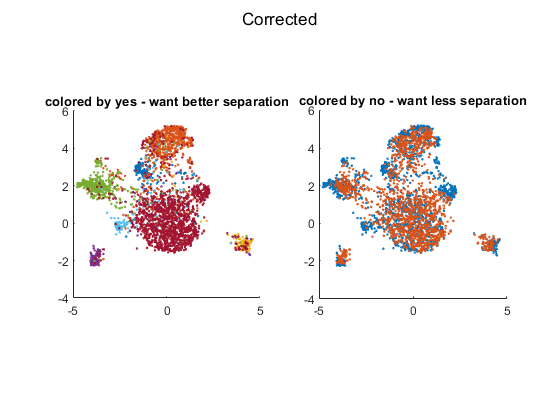

%R = tsne(D, [], 2);
%R = mdscale(D, 2);

figure
sgtitle('Corrected')
subplot(1, 2, 1)
for t = unique(type)'
    scatter(R(yes == t, 1), R(yes == t, 2), 2)
    hold on
end
pbaspect([1 1 1])
title('colored by yes - want better separation')

subplot(1, 2, 2)
scatter(R(no == 1, 1), R(no == 1, 2), 2)
hold on
scatter(R(no == 2, 1), R(no == 2, 2), 2)
pbaspect([1 1 1])
title('colored by no - want less separation')


D = zeros(n);
for jj = 1 : n
    vec = K(jj : n, orth_sub1) - K(jj, orth_sub1) + K(jj, orth_sub2) - K(jj : n, orth_sub2);
    D(jj : n, jj) = sqrt(sum((vec * u) .^ 2, 2));
end

%   ./ s'

D = D + (D' .* (1 - eye(n)));

umap_obj = umap();
umap_obj.metric = 'precomputed';
R = umap_obj.fit(D);

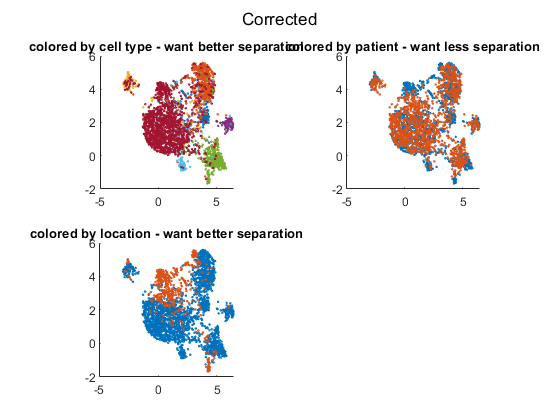

%R = tsne(D, [], 2);
%R = mdscale(D, 2);

figure
sgtitle('Corrected')
subplot(2, 2, 1)
for t = unique(type)'
    scatter(R(yes == t, 1), R(yes == t, 2), 2)
    hold on
end
pbaspect([1 1 1])
title('colored by cell type - want better separation')

subplot(2, 2, 2)
scatter(R(no == 1, 1), R(no == 1, 2), 2)
hold on
scatter(R(no == 2, 1), R(no == 2, 2), 2)
pbaspect([1 1 1])
title('colored by patient - want less separation')
subplot(2, 2, 3)
for t = unique(location)'
    scatter(R(location == t, 1), R(location == t, 2), 2)
    hold on
end
pbaspect([1 1 1])
title('colored by location - want better separation')

umap_obj = umap();
R0 = umap_obj.fit(dataset);

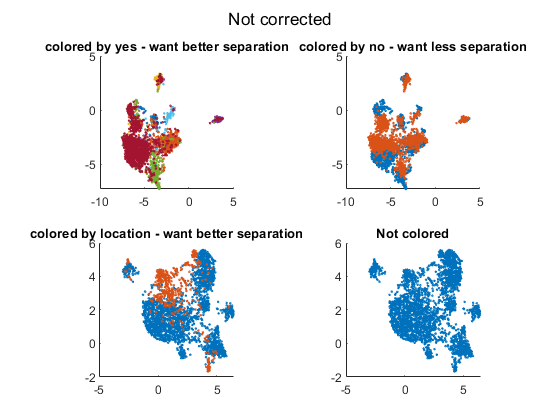

Undefined function or variable 'mitogen'.

%R = tsne(D, [], 2);
%R = mdscale(D, 2);

figure
sgtitle('Not corrected')
subplot(2, 2, 1)
for t = unique(type)'
    scatter(R0(yes == t, 1), R0(yes == t, 2), 2)
    hold on
end
pbaspect([1 1 1])
title('colored by yes - want better separation')

subplot(2, 2, 2)
scatter(R0(no == 1, 1), R0(no == 1, 2), 2)
hold on
scatter(R0(no == 2, 1), R0(no == 2, 2), 2)
pbaspect([1 1 1])
title('colored by no - want less separation')
subplot(2, 2, 3)
for t = unique(location)'
    scatter(R(location == t, 1), R(location == t, 2), 2)
    hold on
end
pbaspect([1 1 1])
title('colored by location - want better separation')

subplot(2, 2, 4)
scatter(R(:, 1), R(:, 2), 2)
pbaspect([1 1 1])
title('Not colored')